%% Initialisation
clear
d = dir('faces/*.pgm');
N = length(d);
I = imread([d(1).folder, '/', d(1).name]);
[rows,cols] = size(I);
M = rows*cols;
A = zeros(M, N); % big matrix, whose columns are the images
%% Read images as columns of the matrix
for j = 1:N
I = imread([d(j).folder, '/', d(j).name]);
A(:,j) = I(:);
end

% Testing how to display image
d

d = 1000×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


A2img = uint8(reshape(A(:,2),[rows,cols]))

A2img = 192×168 uint8 matrix
    94    94    96   102   109   115   110   109   114   116   122   127   127   125   129   132   133   137   137   134   138   145   149   153   157   159   157   157   159   162   156   151   153   153   156   160   164   168   173   175   174   179   180   178   184   191   191   189   191   196
    87    87    94    98   107   113   113   111   115   121   125   129   128   127   130   131   132   134   135   138   146   152   155   157   157   156   154   156   160   159   147   139   152   160   167   163   159   164   171   171   168   177   183   187   191   192   190   190   196   201
    88    91    95   101   105   109   108   108   113   122   126   128   129   130   131   131   134   136   135   140   147   153   156   156   153   153   156   160   158   153   151   150   161   167   168   167   153   146   161   171   175   180   185   191   193   188   186   191   198   201
    87    91    97   102   104   104   102   105   113   120   126  

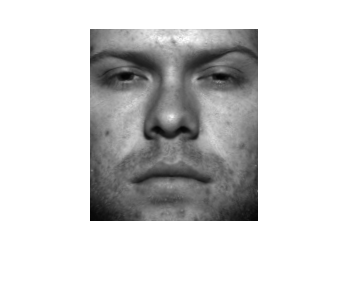

imshow(A2img)

% Calculating mean face
MF = mean(A,2)

MF =    57.5760
   58.1640
   58.5980
   58.5510
   58.3900
   58.6100
   59.0360
   59.4340
   59.5230
   58.9780


MFimg = uint8(reshape(MF,[rows,cols]))

MFimg = 192×168 uint8 matrix
    58    59    61    63    65    67    68    70    71    72    74    75    76    78    80    81    83    85    86    88    89    90    92    93    95    96    97    99   101   103   105   106   108   110   112   114   116   118   120   122   123   124   125   126   128   129   131   132   134   135
    58    60    62    63    65    67    69    70    71    72    73    74    76    78    79    81    83    84    86    87    88    90    91    93    94    95    97    98   100   102   104   106   108   110   112   115   116   118   120   121   123   124   126   127   128   130   131   132   134   135
    59    60    62    64    65    67    69    70    71    72    73    74    76    77    79    80    82    84    85    87    88    89    91    92    94    95    97    98   100   102   104   106   108   110   113   115   116   118   119   121   122   124   125   127   128   129   131   132   134   136
    59    60    62    63    65    67    69    70    71    71    72  

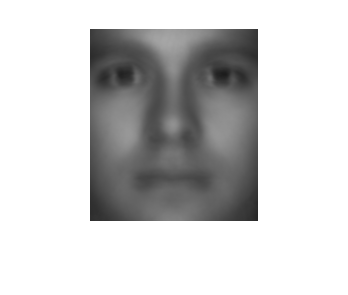

imshow(MFimg)

% Mean centring
MCA = A - MF

MCA =    22.4240   36.4240    1.4240   11.4240   -4.5760   48.4240   36.4240   61.4240   32.4240   61.4240   65.4240   46.4240   10.4240   41.4240  110.4240   99.4240   60.4240   15.4240   16.4240    7.4240  -10.5760   12.4240   -4.5760   -9.5760  -39.5760  -23.5760  -40.5760  -45.5760  -48.5760   28.4240   38.4240   39.4240    9.4240  -15.5760   44.4240   33.4240   52.4240   32.4240   62.4240   63.4240   36.4240    8.4240   54.4240   87.4240   89.4240   51.4240   12.4240   15.4240    8.4240  -10.5760
   22.8360   28.8360    8.8360    8.8360   -6.1640   43.8360   33.8360   59.8360   31.8360   57.8360   61.8360   45.8360   10.8360   39.8360   98.8360   96.8360   59.8360   10.8360   13.8360    3.8360   -9.1640    6.8360  -10.1640  -12.1640  -38.1640  -25.1640  -43.1640  -48.1640  -49.1640   20.8360   37.8360   36.8360    6.8360  -18.1640   43.8360   32.8360   51.8360   23.8360   56.8360   57.8360  -35.1640    6.8360  110.8360   85.8360   87.8360   53.8360   11.8360   12.8360    7.8360  -

% Perform SVD
[U,Sigma,V] = svd(MCA, 'econ')

U =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049   -0.0004   -0.0082    0.0075   -0.0013   -0.0003    0.0060    0.0014    0.0019    0.0111   -0.0007   -0.0008   -0.0043    0.0087    0.0000   -0.0061    0.0079    0.0051    0.0015   -0.0017    0.0079    0.0058   -0.0012    0.0107    0.0082    0.0010   -0.0022   -0.0019   -0.0090   -0.0008    0.0035
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056   -0.0006   -0.0078    0.0066   -0.0016    0.0003    0.0049    0.0016    0.0009    0.0117   -0.0015   -0.0006   -0.0033    0.0079   -0.0007   -0.0053    0.0081    0.0041    0.0011   -0.0014    0.0081    0.0044   -0.0012    0.0104    0.0074    0.0008   -0.0007   -0.0012   -0.0112   -0.0013    0

Sigma = 1.0e+05 *

    1.4981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

V =    -0.0087   -0.0214    0.0011   -0.0223    0.0024   -0.0094    0.0142    0.0088   -0.0064    0.0314   -0.0194    0.0301   -0.0155    0.0448   -0.0067    0.0646   -0.0084    0.0029    0.0146   -0.0214    0.0652   -0.0336    0.0181   -0.0004    0.0173   -0.0217    0.0065   -0.0371    0.0130   -0.0098    0.0131   -0.0082    0.0287   -0.0071    0.0108   -0.0073    0.0195    0.0602   -0.0282    0.0090   -0.0286   -0.0045    0.0272    0.0057    0.0194   -0.0164    0.0036    0.0077    0.0084    0.0037
   -0.0115   -0.0273   -0.0359   -0.0185    0.0066   -0.0085    0.0048    0.0066   -0.0342    0.0259   -0.0183    0.0353   -0.0051    0.0365    0.0047    0.0559   -0.0265    0.0015    0.0072   -0.0085    0.0952   -0.0342    0.0239    0.0396    0.0230   -0.0092    0.0222   -0.0401    0.0105   -0.0245   -0.0140   -0.0307    0.0168   -0.0464   -0.0068   -0.0286    0.0089    0.0536   -0.0243    0.0103   -0.0305    0.0021    0.0194   -0.0032    0.0101    0.0001    0.0169   -0.0045   -0.0108    0

% Test mean centred image
MCA2img = uint8(reshape(MCA(:,2),[rows,cols]))

MCA2img = 192×168 uint8 matrix
   36   35   35   39   44   48   42   39   43   44   48   52   51   47   49   51   50   52   51   46   49   55   57   60   62   63   60   58   58   59   51   45   45   43   44   46   48   50   53   53   51   55   55   52   56   62   60   57   57   61
   29   27   32   35   42   46   44   41   44   49   52   55   52   49   51   50   49   50   49   51   58   62   64   64   63   61   57   58   60   57   43   33   44   50   55   48   43   46   51   50   45   53   57   60   63   62   59   58   62   66
   29   31   33   37   40   42   39   38   42   50   53   54   53   53   52   51   52   52   50   53   59   64   65   64   59   58   59   62   58   51   47   44   53   57   55   52   37   28   42   50   53   56   60   64   65   59   55   59   64   65
   28   31   35   39   39   37   33   35   42   49   54   54   52   51   52   53   54   55   53   52   57   64   66   64   56   54   59   60   54   49   53   58   61   62   54   48   36   24   34   49   59   61   63 

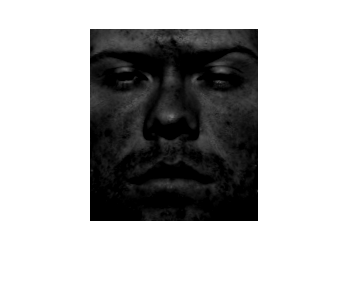

imshow(MCA2img)

diag(Sigma)

ans = 1.0e+05 *

    1.4981
    1.3162
    0.8023
    0.5178
    0.4554
    0.4080
    0.3869
    0.3534
    0.2989
    0.2900
